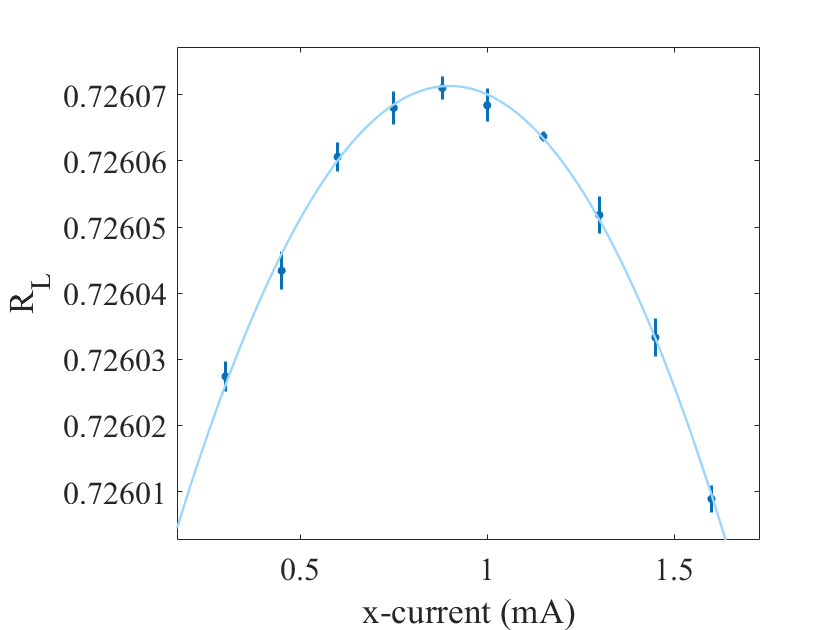


close all;
clear all;

maindir = ['\\Artemis-pc\Data\2026-09-09\' ...
    'xFit_near'];
save_data = 0;

% x = 1e-3*([300 ...
%     450 600 750 ...
%     880 1000 1150 ...
%     1300 1450 1600]);
% y = [0.7260248 ...
%     0.7260472 0.7260589 0.7260689 ...
%     0.7260714 0.7260700 0.7260659 ...
%     0.7260552 0.7260327 0.7260119];
% err = 1e-7*[23 ...
%     27 10 11 ...
%     12 10 12 ...
%     12 19 12];

x = 1e-3*([300 ...
    450 600 750 ...
    880 1000 1150 ...
    1300 1450 1600]);
y = [0.7260274 ...
    0.7260434 0.7260606 0.7260680 ...
    0.7260710 0.7260684 0.7260637 ...
    0.7260518 0.7260333 0.7260089];
err = 1e-7*[23 ...
      29 22 25 ...
      17 25 8 ...
      28 29 21];

w = 1./err.^2;

f1 = figure; hold on;
errorbar(x,y,err,'.','CapSize',0,...
    'MarkerSize',14,'LineWidth',1.5,...
    'Color',[0.04,0.44,0.71]);

margin_per = 0.1;

xmin = min(x)-margin_per*(max(x)-min(x));
xmax = max(x)+margin_per*(max(x)-min(x));

ymin = min(y)-margin_per*(max(y)-min(y));
ymax = max(y)+margin_per*(max(y)-min(y));

xlim([xmin xmax]);
ylim([ymin ymax]);

set(gcf,'Visible','on');

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData( x, y, w );

% 设置 fittype 和选项。
ft = fittype( 'a*(x-x0)^2+R0', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.726 0 0.92];
opts.Weights = weights;

% 对数据进行模型拟合。
[fitted, gof] = fit( xData, yData, ft, opts );
interval = confint(fitted);
a = fitted.a;
a_err = abs(interval(1,2)-interval(2,2))/4;
R0 = fitted.R0;
R0_err = abs(interval(1,1)-interval(2,1))/4;
x0 = fitted.x0;
x0_err = abs(interval(1,3)-interval(2,3))/4;

% 绘制数据拟合图。
l = plot(fitted);
l.LineWidth = 1.2;
l.Color = [0.61 0.84 1];

legend off;

set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('x-current (mA)');
ylabel('R_L');
box on;


if save_data == 1
    savefig(f1,[maindir,'.fig']);
    saveas(f1,[maindir,'.png']);
    %
    save([maindir,'.mat']);
end